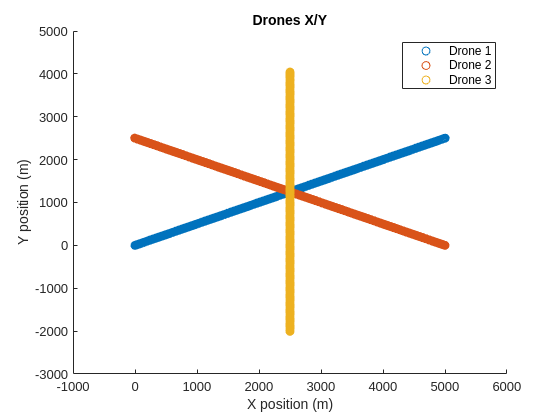

position_files = dir("drone_*_pos.json");
num_position_files = length(position_files);
for i=1:num_position_files
    position_files(i).name = convertCharsToStrings(position_files(i).name);
end
position_files = [position_files.name];

drones = strings(1, num_position_files);

for i=1:num_position_files
    drones(i) = "Drone " + i;
end

max_num_points = -1;
for file=position_files
    str = fileread(file);

    json = jsondecode(str);
    positions = json.positions;

    if length(positions) > max_num_points
        max_num_points = length(positions);
    end
end

X = [];
Y = [];
Z = [];
for file=position_files
    str = fileread(file);

    json = jsondecode(str);
    positions = json.positions;

    len = length(positions);
    if len < max_num_points
        for i=len:max_num_points
            positions(i).x = NaN;
            positions(i).y = NaN;
            positions(i).z = NaN;
        end
    end
    
    posx = [positions.x];
    posy = [positions.y];
    posz = [positions.z];

    X = [X, posx'];
    Y = [Y, posy'];
    Z = [Z, posz'];
end

scatter(X, Y);
title('Drones X/Y');
legend(drones);
xlabel('X position (m)');
ylabel('Y position (m)');

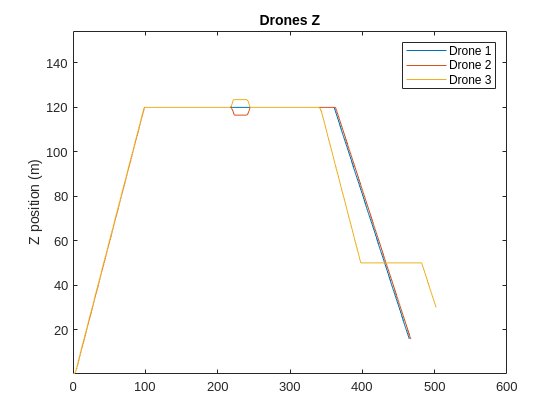


plot(Z);
title('Drones Z');
legend(drones);
Z = reshape(Z.',1,[]);
ylim([min(Z) max(Z)] .* 1.25);
ylabel('Z position (m)');

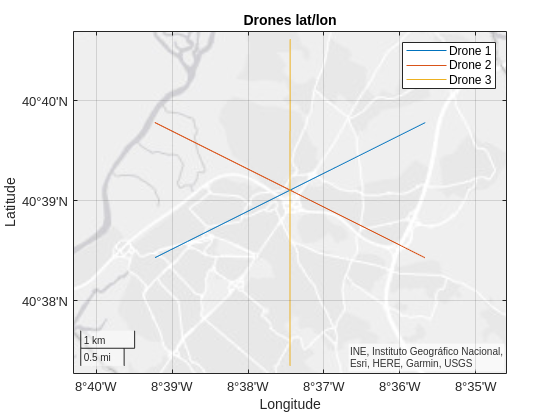

coord_files = dir("drone_*_coords.json");
num_coord_files = length(coord_files);
for i=1:num_coord_files
    coord_files(i).name = convertCharsToStrings(coord_files(i).name);
end
coord_files = [coord_files.name];

max_num_points = -1;
for file=coord_files
    str = fileread(file);

    json = jsondecode(str);
    coords = json.coordinates;

    if length(coords) > max_num_points
        max_num_points = length(coords);
    end
end

lat = [];
lon = [];
for file=coord_files
    str = fileread(file);

    json = jsondecode(str);
    coords = json.coordinates;

    len = length(coords);
    if len < max_num_points
        for i=len:max_num_points
            coords(i).latitude = NaN;
            coords(i).longitude = NaN;
        end
    end
    
    lats = [coords.latitude];
    lons = [coords.longitude];

    lat = [lat, lats'];
    lon = [lon, lons'];
end

for i=1:num_coord_files
    geoplot(lat(:, i), lon(:, i));
    hold on;
end
hold off;
title('Drones lat/lon');
legend(drones);

% geobasemap streets;